
PWM = load("C:\Users\rpumpo\Desktop\my-icub-models-copy\boards\amcbldc\pos.mat")

PWM = struct with fields:
    ans: [1×1 timeseries]

velocity = load("C:\Users\rpumpo\Desktop\my-icub-models-copy\boards\amcbldc\vel.mat")

velocity = struct with fields:
    ans: [1×1 timeseries]

V_alim = 17.98 ;  % Voltage used to collect datas
%Determine the sample time for collecting data

t  = round(PWM.ans.Time * 1e3);
Ts = mode(diff(t)) / 1e3;
fprintf("Sample time Ts = %g\n", Ts);

Sample time Ts = 0.01


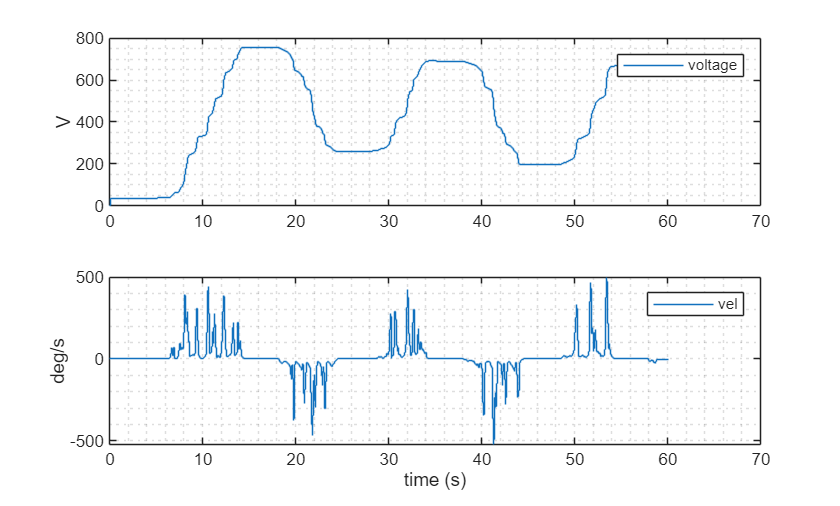

n  = 1;    % sample time of streaming encoder data 

t   = downsample(PWM.ans.Time,n);
%pwm = downsample(PWM.ans.Data/100*V_alim, n);
pwm = downsample(PWM.ans.Data, n);
v = downsample(velocity.ans.Data,n);
figure;
data = iddata(pwm,v,n*Ts);

figure;
tiledlayout(2, 1);
h1 = nexttile;
stairs(t, pwm);
ylabel("V");
grid minor;
legend({"voltage"});

h2 = nexttile;
stairs(t, v);
ylabel("deg/s");
grid minor;
legend("vel");

xlabel("time (s)");
linkaxes([h1, h2], 'x');

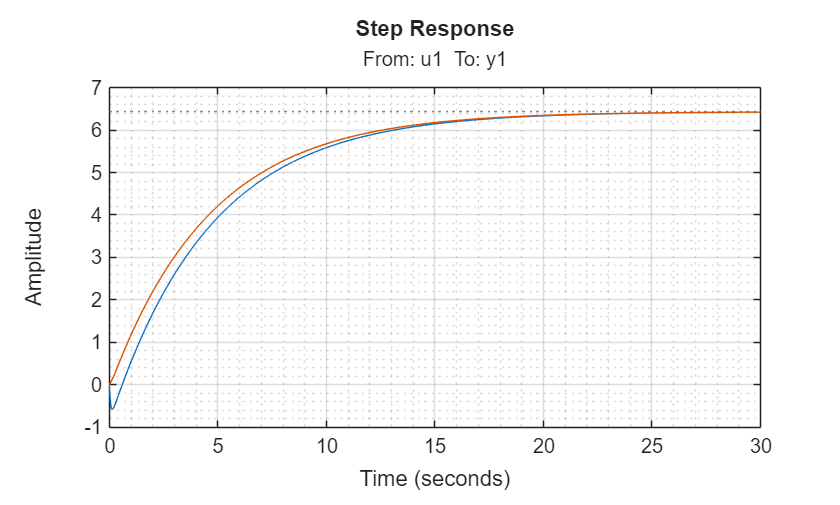


ssOpts = ssestOptions;
ssOpts.Display = 'off';
ssOpts.Focus = 'simulation';
ssOpts.InitialState = 'zero';

order = 2;
ss = ssest(data, order, 'Form', 'free', 'DisturbanceModel', 'none', ssOpts);

G = zpk(ss);
Gred = G;
Gred.Z{1} = [];
Gred.K = Gred.K * dcgain(G) / dcgain(Gred);

figure;
stepplot(G,Gred);
grid minor;

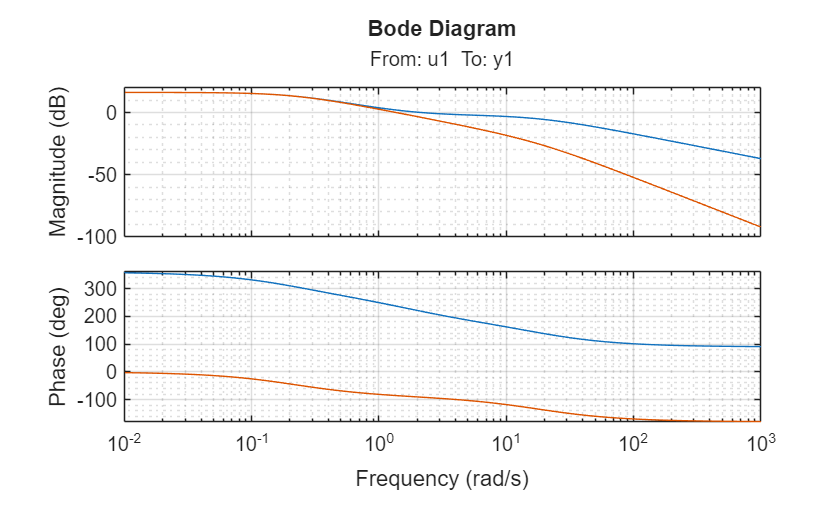


figure;
bodeplot(G, Gred)
grid minor;

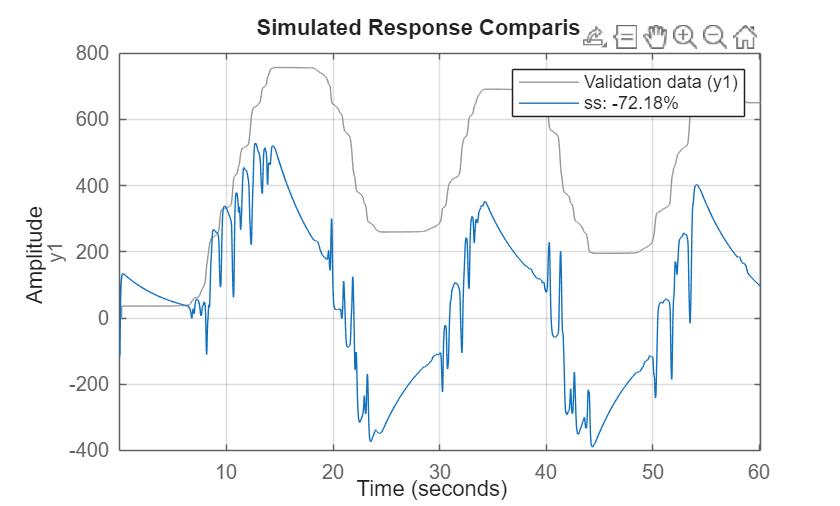


figure;
compare(data,ss);
grid minor;

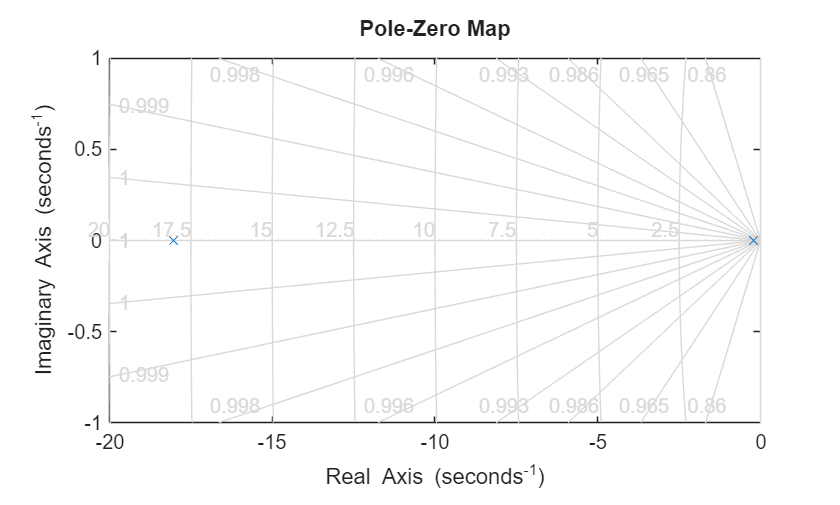


figure;
pzmap(Gred);
grid minor;

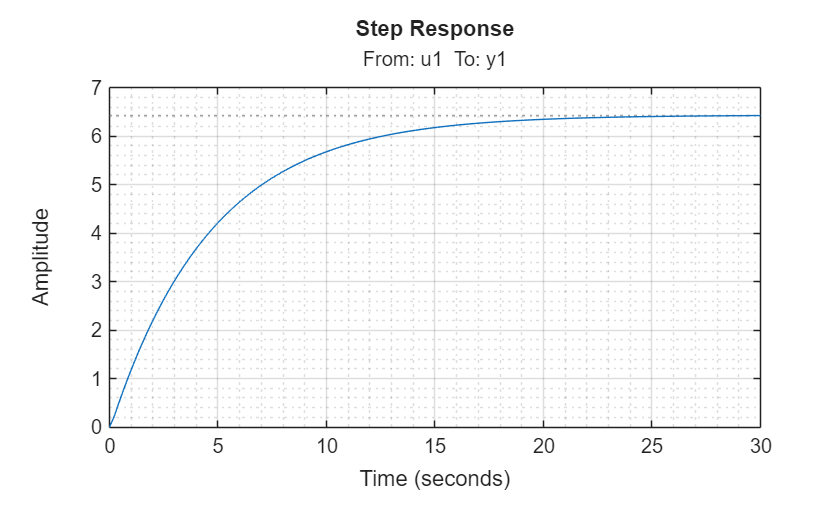


figure;
stepplot(Gred);
grid minor;

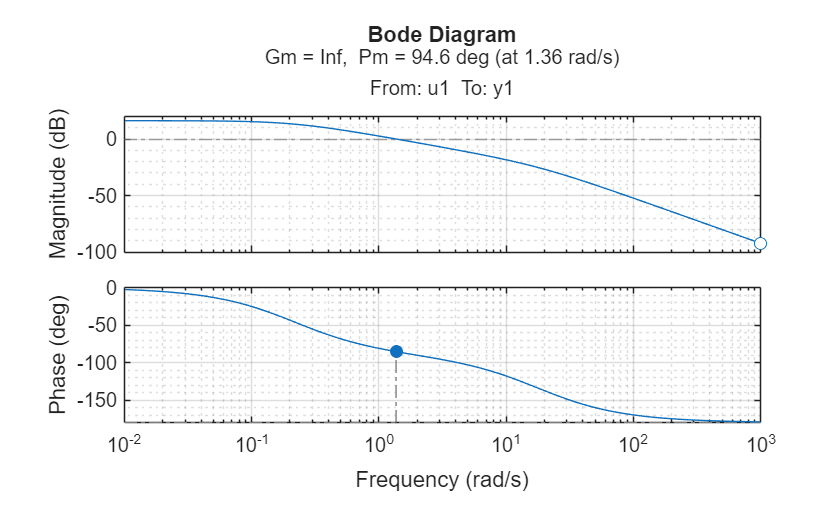


figure;
margin(Gred);
grid minor;

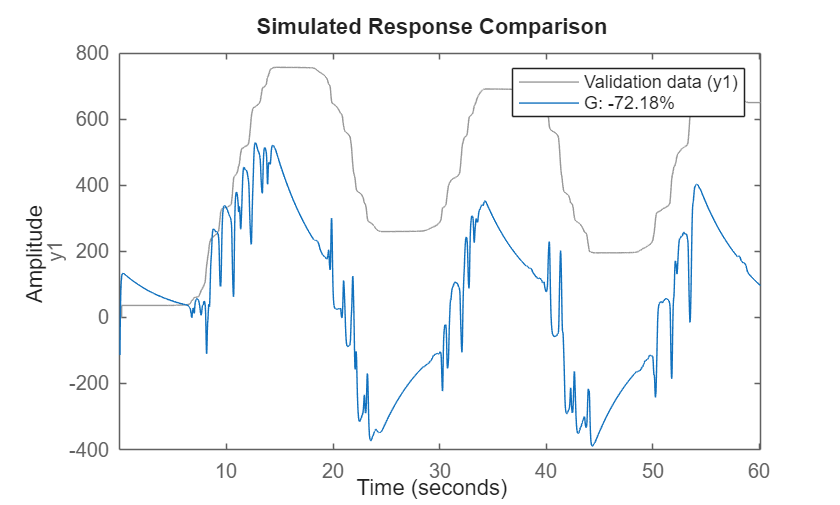

compare(data,G)

## Controller

plant = ss;
C0  = tunablePID('VelocityPID', 'PI');

C0.Kp.Minimum = 0.01;
C0.Kp.Maximum = 1000;

C0.Ki.Minimum = 0.01;
C0.Ki.Maximum = 1000;

AP1 = AnalysisPoint('AP1');
sys = feedback(C0 * plant * AP1, 1);
sys.InputName = "r";
sys.OutputName = "y";

fc = 1.5; % Hz
wc = 2*pi * fc;
responsetime = 2/wc;  % s
dcerror      = 0;       % perc
maxOvershoot = 1;       % perc
gainMargin   = 3;       % dB
phaseMargin  = 60;      % deg

Rtrack = TuningGoal.Tracking('r', 'y', responsetime, dcerror);
Rov = TuningGoal.Overshoot('r', 'y', maxOvershoot);
Rmargin = TuningGoal.Margins('AP1', gainMargin, phaseMargin);     
sys_tuned = systune(sys, [Rmargin, Rov], Rtrack);

Final: Soft = 8.99, Hard = 8.2647, Iterations = 44



C = getBlockValue(sys_tuned, 'VelocityPID')


C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.847, Ki = 0.175
 
Name: VelocityPID
Continuous-time PI controller in parallel form.


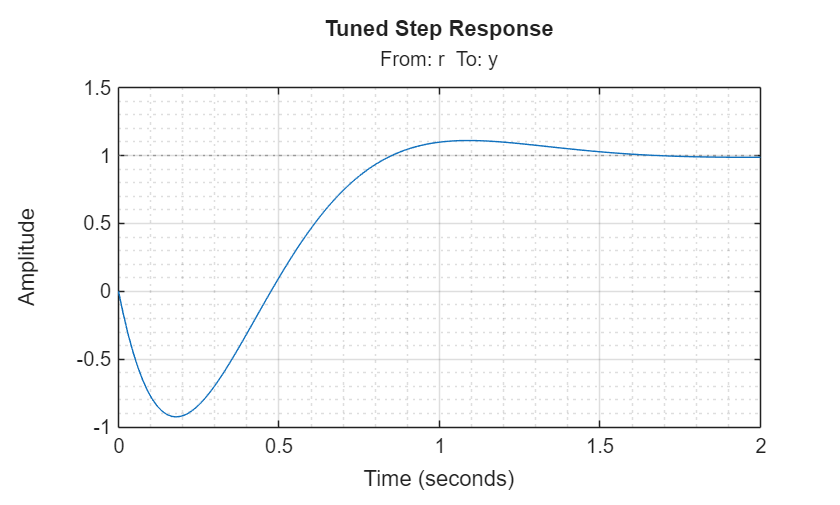


figure;
stepplot(sys_tuned);
title('Tuned Step Response');
grid minor;

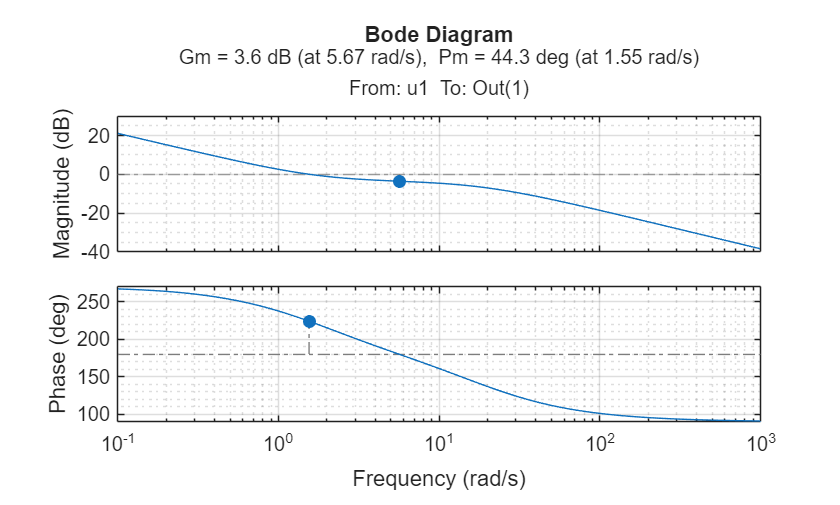


figure;
margin(C * plant);
grid minor;